need to:

not hardcode pan and tilt

calibrate distance to voltage

use distance not voltage

also color close/far?

D = load('sensorDatav1.mat');

Calibrate Distance to Voltage

calibrateData = [15, 2.75;
    20, 2.5;
    30, 2;
    40, 1.5;
    50, 1.25;
    60, 1.05;
    70, 0.9;
    80, 0.8;
    90, 0.75;
    100, 0.65
    110, 0.6
    120, 0.55
    130, 0.5];
calibrateDataDistance = calibrateData(:, 1);
calibrateDataVoltage = calibrateData(:, 2);
%cftool
a = 3.1121;
b = -0.0158;
x = linspace(0, 140, 140);
calCurve = a*exp(b*x);

figure(1)
hold on
plot(calibrateDataDistance, calibrateDataVoltage, "x")
plot(calCurve)
hold off

outputDistance = a*exp(b*sensorData);

nDegrees = 4;
% out4x4 = reshape(sensorData, [4, 4])
% %cut it into a 4 by 4

panValues = [0,0,0,0, 0.5,0.5,0.5,0.5, 1,1,1,1, 1.5,1.5,1.5,1.5]

panValues =          0         0         0         0    0.5000    0.5000    0.5000    0.5000    1.0000    1.0000    1.0000    1.0000    1.5000    1.5000    1.5000    1.5000


tiltValues = [0, 0.3, 0.6, 1, 0, 0.3, 0.6, 1, 0, 0.3, 0.6, 1, 0, 0.3, 0.6, 1]

tiltValues =          0    0.3000    0.6000    1.0000         0    0.3000    0.6000    1.0000         0    0.3000    0.6000    1.0000         0    0.3000    0.6000    1.0000



Az = panValues % Azimuth - pan angle

Az =          0         0         0         0    0.5000    0.5000    0.5000    0.5000    1.0000    1.0000    1.0000    1.0000    1.5000    1.5000    1.5000    1.5000


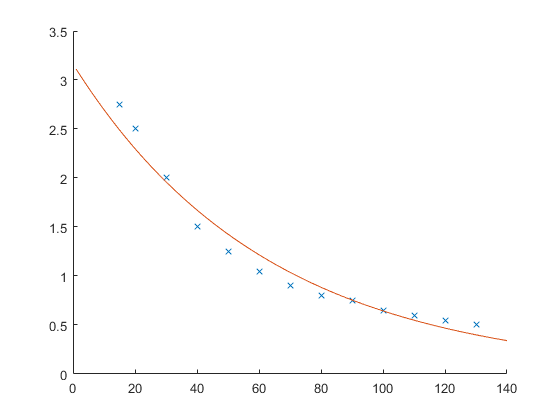

cm =      0     1     1


El = tiltValues; % Elevation - tilt angle
Rd = outputDistance; % voltage data

cn = ceil(max(El));                                             % Number Of Colors
cm = colormap(jet(cn))


[x,y,z]=sph2cart (Az,El,Rd)

x =     2.9868    2.8972    2.5606    1.6732    2.6200    2.5466    2.2416    1.4723    1.6165    1.5685    1.3791    0.9027    0.2111    0.2054    0.1810    0.1188


y =          0         0         0         0    1.4313    1.3912    1.2246    0.8043    2.5176    2.4428    2.1479    1.4059    2.9773    2.8964    2.5518    1.6751


z =          0    0.8962    1.7518    2.6058         0    0.8977    1.7475    2.6129         0    0.8980    1.7463    2.6020         0    0.8982    1.7502    2.6153


% plot3(x,y,z,'o')

% zscaled = z*10                                                 % May Be Necessary To Scale The Colour Vector
% cn = ceil(max(zscaled))                                        % Number Of Colors (Scale AsAppropriate)
% cm = colormap(jet(cn))                                         % Define Colormap

% ahhhhhh = cm(ceil(zscaled),:)

% scatter3(x,y,z)
% scatter3(x, y, z, [])
scatter3(x, y, z, [], cm(ceil(zscaled),:))

Index in position 1 is invalid. Array indices must be positive integers or logical values.

scatter3(x, y, z, [], cm(ceil(zscaled),:), 'filled')
